# Equation fitting for data obtained from ImageJ particle tracking and @msdanalyzer diffusion analysis

Prior to running this code, you need to download and install @msdanalyser from here: [https://tinevez.github.io/msdanalyzer/](https://tinevez.github.io/msdanalyzer/) @msdanalyzer imposes that the tracks you give to it are formatted in the following way: [ Ti Xi Yi ...]. So if we generate a track with 50 measurements in a 2D diffusion problem, we must generate a 50 x 3 double array per particle. The input file for this code should be a cell, where each array is the [ Ti Xi Yi ] matrix for each particle trajectory. Use the code "tracks_from_ImageJ_data" to convert ImageJ data to tracks cell needed as input here. Import track data in the cell format required for analysis with @msdanalyzer.

Soli Deo Gloria

## Compute some constants needed later

%%%%%%%%%%% Must run this

N_TIME_STEPS = 1428; % This will be needed for plotting the histogram of velocities
SPACE_UNITS = 'um'; % The units are needed to initiate the @msdanalyzer
TIME_UNITS = 's';


% Compute some parameters we will need for fitting the velocity histograms
kB = 1.38064852*(10^(-23)); % Boltzmann constant in units of [(m^2)*kg*(s^-2)*(K^-1)]
t_d = 0.03; % Dust temperature in units of [eV] (assumed equal to room temperature)
T_d = t_d*(1.602176634*10^(-19)); %dust temperature in units of [J]
K_d = T_d/kB; %dust temp in units of Kelvin
r_d = 4.6*(10^(-6)); %radius of spherical dust particles in units of [m]
V_d = (4/3)*pi*(r_d)^3; %volume of a single dust particle in units of [m^3]
rho_d = 1500; %density of dust particle material in units of [kg*(m^-3)]
%(here melamine-formaldehyde)
m_d = V_d*rho_d; %mass of a single dust particle
v_d = sqrt(T_d/m_d)*10^(6); %dust thermal speed in units of [um/s]

## Creating MSD and Essential MA object 

ma = msdanalyzer(2, SPACE_UNITS, TIME_UNITS); %dimensionality and Specify units for the msdanalyzer
ma = ma.addAll(tracks); % Add 'tracks' data 
ma = ma.computeDrift('velocity');
ma = ma.computeVCorr;

Computing velocity autocorrelation of 4663 tracks... Done.


ma = ma.computeMSD;% Compute MSD for each particle.

Computing MSD of 4663 tracks...  4Done.


ma.msd

ans = 4663×1 cell array
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}
    {1429×4 double}


save(['46Pa_07mA_msd_data_Cam1_nhds'],'ma') % Save msd for specific case 

## Separate MSD for X and Y

%%Computing MSD for x component seperately 
%%seperately and then the workspace must be cleared to do 
%%the next msd calculation and graph fitting
%%first load the msd data ma object 
%%example: Total70Pa_0_35mA_msd_data.mat

tracks=ma.tracks;
ma=ma.computeDrift('velocity');

xtracks = [];
for i=1:numel(tracks);
    particle = tracks{i,1}; %this pulls the i'th particle out of the cell tracks
    xtracks{i,1} = particle(:,[1,2]); %this puts the time and position columns into a new cell
end 

%create separate ma object called xma 
xma = msdanalyzer(1, SPACE_UNITS, TIME_UNITS);
xma = xma.addAll(xtracks); % Add the sample tracks for x 
xma = xma.computeDrift('velocity');
xma = xma.computeVCorr;
xma = xma.computeMSD; % Compute MSD for each particle.
xma.msd

save(['MDPX_B2_02_rf1_06_P10_3Pa_xMSD'],'xma') % Save x msd for specific case 

%%Computing MSD for y component seperately 
%%example: Total70Pa_0_35mA_msd_data.mat
 
ma=ma.computeDrift('velocity');
tracks=ma.tracks;

ytracks = [];
for i=1:numel(tracks);
    particle = tracks{i,1}; %this pulls the i'th particle out of the cell tracks
    ytracks{i,1} = particle(:,[1,3]);
end 

yma = msdanalyzer(1, SPACE_UNITS, TIME_UNITS);
yma = yma.addAll(ytracks); % Add the sample tracks for y 
yma = yma.computeDrift('velocity');
yma = yma.computeVCorr;
yma = yma.computeMSD; % Compute MSD for each particle.
yma.msd

save(['MDPX_B2_02_rf1_06_P10_3Pa_yMSD'],'yma') % Save y msd for specific case into current path

%%Double check all tracks and look at drift for conceptual understanding and experimental verification
figure
axis([0 15000 -5000 6000])
ma.plotTracks
ma.labelPlotTracks
ma = ma.computeVCorr;
figure
ma.plotMeanVCorr
figure
ma.plotDrift

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%create drift over time plot%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dtimex=ma.drift(:,1);
dposx=ma.drift(:,2);
xdrift = (dposx(end)-dposx(1))./(dtimex(end)-dtimex(1));

dtimey=ma.drift(:,1);
dposy=ma.drift(:,3);
ydrift = (dposy(end)-dposy(1))./(dtimey(end)-dtimey(1));

figure;
hold on
xlabel('Time (seconds)')
ylabel('Position (um)')
plot(dtimex,dposx);
plot(dtimey,dposy);
title('Drift over Time MDPX B2.02 rf1.06 P10.3Pa');
legend(['x-velocity drift=' num2str(xdrift)],['y-velocity drift=' num2str(ydrift)]);

## Creating Tracks without Drift

%%run the above code first to observe amount of drift

tracks = ma.tracks;
Total_drift = ma.drift;
roundedTotal_drift=round(Total_drift(:,1),4);
number_particles=numel(tracks);

track_nodrift=[];

for i=1:number_particles;
    particle=tracks{i,1};
    time = particle(:,1);
    framecount = numel(particle)/3; %not an actuall time just a counter for each particle. 
    % It is divided by 3 because numel(particle) counts amount of time
    % data, x data, and y data, thus divide by 3 since the length of all of these is the same
    % Extract data from Total_drift array based on matching values in ith particle time array
    roundedtime = round(time,4);
    matchingRows = ismember(roundedTotal_drift(:, 1), roundedtime);
    drift = Total_drift(matchingRows, 2:3);
    
    particle_nodrift=zeros(framecount,1);
    for j=1:framecount;
        particle_nodrift(j,1:2) = particle(j,2:3)-drift(j,1:2);
    end

    track_nodrift{i,1}=particle_nodrift;

end

%%%PLot N tracks with no drift%%%
figure
axis([0 15000 -1000 4000])
hold on

N = 1000; % Set the desired number of tracks to see. for all set N=numel(track_nodrift)
M = numel(track_nodrift);

for i = 1:min(N, numel(track_nodrift))
    plot(track_nodrift{i}(:, 1), track_nodrift{i}(:, 2));
end
title(['C1 Tracks with drift subtraction 30Pa 07mA ' num2str(N) 'above10frs']);

%%%Plot N tracks with drift%%%
figure
axis([0 15000 -1000 4000])
hold on

N = 1000; % Set the desired number of tracks to see. for all set N=numel(track_nodrift)
M = numel(tracks);

for i = 1:min(N, numel(tracks))
    plot(tracks{i}(:, 2), tracks{i}(:, 3));
end
title(['C1 Tracks with drift 30Pa 07mA ' num2str(N) 'above10frs']);


## Plotting full MSD

clf;
%interestingly if you disconnect from your network this may cause some issues
ma = ma.computeDrift('velocity'); %compute drift to subtract from MSD
figure 
%Plot the averaged MSD
ma.plotMeanMSD(gca, false) %true puts the grey "std" region on 

Computing MSD of 4663 tracks...  2154/ 4663

% The grayed area represents the weighted standard deviation over all separate MSD tracks
set(gca,'FontSize',18); %Set axis fontsize to 18
xlim([0 8])

% with error bars
mmsd = ma.getMeanMSD(1:numel(ma.msd)); %was getting indices error with empty input so I changed it to 1:numel(ma.msd)
t = mmsd(:,1);
x = mmsd(:,2);
dx = mmsd(:,3) ./ sqrt(mmsd(:,4));
errorbar(t, x, dx, 'k') %this plots in a separate figure and will be overlayed later


clf;
% Compute mean MSD for separate x and y directions
ma = ma.computeDrift('velocity');
figure
ma.plotMeanMSD(gca,false)
set(gca,'FontSize',18); %Set axis fontsize to 18
xlim([0 8])

xma = xma.computeDrift('velocity');
figure 
xma.plotMeanMSD(gca,false)
set(gca,'FontSize',18); %Set axis fontsize to 18
xlim([0 8])

yma = yma.computeDrift('velocity');
figure
yma.plotMeanMSD(gca,false)
set(gca,'FontSize',18); %Set axis fontsize to 18
xlim([0 8])

%%%This is to combine multiple already created and saved MSD figures
% List of full path names for the figure files to be combined
filePaths = {
    'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\70Pa1mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\70Pa07mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\70Pa035mA NHDS MSD.fig', ... % Blue shades
    'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\46Pa1mA NHDS MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\46Pa07mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\46Pa035mA MSD.fig', ... % Red shades
    'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\30Pa1mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\30Pa07mA MSD.fig', 'C:\Users\theve\Desktop\Research\PK-4 Experiment\Newest PK4 Data analysis and Ideas\Cam1 results\All MSD without STD\30Pa035mA MSD.fig'      % Green shades
};


% Create a new figure
combinedFigure = figure;

% Define color sets
blueShades = [0 0 1; 0 0.5 1; 0 0.8 0.9];     % Shades of blue
redShades = [1 0 0; 1 0.1 0.7; 1 0.7 0.7];   % Shades of red
greenShades = [0 1 0; 0.1 1 0.7; 0.7 1 0.7]; % Shades of green

% Loop through each file
for i = 1:numel(filePaths)
    % Load the figure file
    loadedFig = openfig(filePaths{i}, 'invisible');
    
    % Get the handle of the axes in the loaded figure
    axesHandle = gca(loadedFig);
    
    % Determine the color set based on the index
    if i <= 3
        colorSet = blueShades(i,:);
    elseif i <= 6
        colorSet = redShades(i-3,:);
    else
        colorSet = greenShades(i-6,:);
    end
    
    % Get the number of lines in the axes
    numLines = numel(axesHandle.Children);
    
    % Copy the line data onto the combined figure with different colors
    for j = 1:numLines
        lineData = axesHandle.Children(j).YData;
        lineColor = colorSet(rem(j-1, size(colorSet, 1)) + 1, :);
        normalizedData = lineData / max(lineData);  % Normalize YData
        
        figure(combinedFigure);  % Switch focus to the combined figure
        hold on;
        plot(lineData, 'Color', lineColor,'LineWidth',1.5); %choose lineData or normalizedData
      
    end
    
    % Close the loaded figure
    close(loadedFig);
end

% Adjust the layout if needed
% For example, you can use the 'subplot' function to arrange the subplots


% Set legend labels for each set of three figures
legendLabels = {
    '70Pa 1mA', '70Pa 0.7mA', '70Pa 0.35mA NHDS', ...
    '46Pa 1mA NHDS', '46Pa 0.7mA', '46Pa 0.35mA', ...
    '30Pa 1mA', '30Pa 0.7mA', '30Pa 0.35mA'
};

% Add a legend
legend(legendLabels);

% Add title and axis labels
title('Combined MSD');
xlabel('Delay (\tau)');
ylabel('MSD(\tau)');
axis([0 1000 0 1000000])

ax = gca;
ax.XTickLabel = {'0','2','4','6','8','10'};


## Polynomial Fitting for MSD

%after calculating Mean MSD you can add the % comment, so as to not repeat MeanMSD
%calculation each time. This way you can just modify and check the fitting
A = ma.getMeanMSD(1:numel(ma.msd));

Computing MSD of 4663 tracks...  4Done.


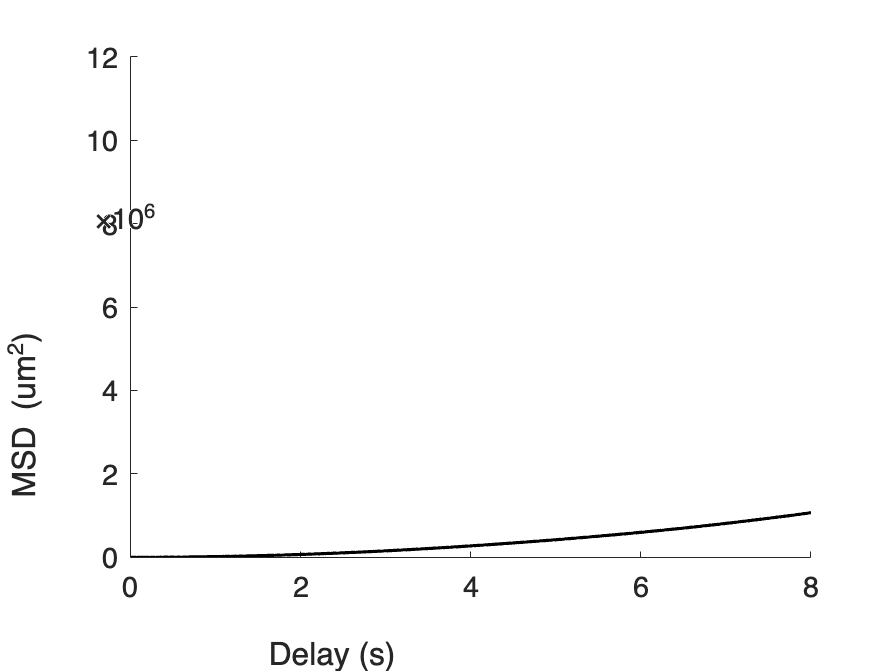

t = A(:, 1); % delay vector
msd = A(:, 2); % msd
std_msd = A(:, 3); % we will use inverse of the std as weights for the fit
std_msd(1) = std_msd(2); % avoid infinity weight
line_fit_limit = 0.9; % this is how much of the data as a percent will be fitted
delayfit = line_fit_limit * max(t); % maximum t value for delay fit
plot_thickness = 2;

% Define the polynomial fits
polyFits = struct('start', {}, 'finish', {}, 'coefficients', {});

% Add polynomial fits as needed
polyFits(1).start = 3; % Start of the first polynomial fit
polyFits(1).finish = 6; % End of the first polynomial fit
polyFits(1).coefficients = [0, 2]; % Starting Coefficients of the polynomial fit

% polyFits(2).start = 2; % Start of the second polynomial fit
% polyFits(2).finish = 6; % End of the second polynomial fit
% polyFits(2).coefficients = [0, 1.5]; 
% 
% polyFits(3).start = 6; % Start of the third polynomial fit
% polyFits(3).finish = 7; % End of the third polynomial fit
% polyFits(3).coefficients = [0, 1.5]; 
% 
% polyFits(4).start = 4; % Start of the fourth polynomial fit
% polyFits(4).finish = 11; % End of he fourth polynomial fit
% polyFits(4).coefficients = [0, 1.5]; 

% polyFits(5).start = 11; % Start of the fith polynomial fit
% polyFits(5).finish =16; % End of the fith polynomial fit
% polyFits(5).coefficients = [0, 1.5]; 
% 
% polyFits(6).start = 16.5; % Start of the fith polynomial fit
% polyFits(6).finish = 18; % End of the fith polynomial fit
% polyFits(6).coefficients = [0, 1]; 

% Power law fit to the data
fitResults = cell(numel(polyFits), 1);
colors = {'r', 'g', 'b', 'm', 'c','y'}; % Add more colors if needed

figure; % Create a new figure
hold on;

bars = A(:,3) ./ sqrt(A(:,4));
% Plot the data in black with specified thickness and low opacity error bars
errorbar(t, msd, bars, 'Color', [0.7 0.7 0.7 0.5]);
plot(t, msd, 'k', 'LineWidth', plot_thickness);
legendText = {'Errorbars','Data'};


for i = 1:numel(polyFits)
    startIdx = find(t >= polyFits(i).start, 1);
    finishIdx = find(t <= polyFits(i).finish, 1, 'last');
    weights = 1./std_msd(startIdx:finishIdx);
    
    myfittype = fittype('a*t^b',...
        'dependent', 'msd', 'independent', 't',...
        'coefficients', {'a', 'b'});
    
    [fitResults{i}.fit, fitResults{i}.gof] = fit(t(startIdx:finishIdx), msd(startIdx:finishIdx), myfittype, 'Weights', weights, 'StartPoint', polyFits(i).coefficients);
    
    % Store the fit exponent for the legend
    polyFits(i).exponent = fitResults{i}.fit.b;
    
    % Plot the fit with a different color
    colorIdx = mod(i-1, numel(colors)) + 1;
    
    % Define the range of t for plotting
    t_range = linspace(polyFits(i).start, polyFits(i).finish, 100);
    
    % Plot only within the specified range for this fit
    plot(t_range, fitResults{i}.fit(t_range), colors{colorIdx},'LineWidth',1.5);
    
    % Add the fit label to the legend
    legendText{end+1} = ['Fit ' num2str(i) ' (Alpha = ' num2str(polyFits(i).exponent) ')'];
    
end

legend(legendText, 'Location', 'best', 'AutoUpdate', 'off');
title('MDPX B2.02 rf1.06 P10.3Pa MSD');
ma.labelPlotMSD;

% Error Calculation of the fits 
% Needs to be normalized since y axis magnitude can be in small units such
% as in micrometers^2/s with MSD ~ 10^6
fprintf('\n--- Normalized Fit Statistics ---\n');


--- Normalized Fit Statistics ---



for i = 1:numel(polyFits)
    % Fit range
    startIdx = find(t >= polyFits(i).start, 1);
    finishIdx = find(t <= polyFits(i).finish, 1, 'last');

    % Data in fit range
    t_fit = t(startIdx:finishIdx);
    y_fit = msd(startIdx:finishIdx);
    y_pred = fitResults{i}.fit(t_fit);

    % Residuals and scale
    residuals = y_fit - y_pred;
    scale = max(y_fit);  % or mean(y_fit) if preferred

    % R^2 
    SS_res = sum(residuals.^2);
    SS_tot = sum((y_fit - mean(y_fit)).^2);
    R_squared = 1 - SS_res / SS_tot;

    % Normalized RMSE
    RMSE_raw = sqrt(mean(residuals.^2));
    RMSE_norm = RMSE_raw / scale;

    % Normalized Chi^2/dof
    chi_squared = sum((residuals ./ scale).^2);
    dof = length(t_fit) - length(polyFits(i).coefficients);
    reduced_chi_squared = chi_squared / dof;

    % Print
    fprintf('Fit %d:\n', i);
    fprintf('  R^2           = %.4f\n', R_squared);
    fprintf('  RMSE          = %.4e\n', RMSE_raw);
    fprintf('  RMSE/scale    = %.4e (normalized)\n', RMSE_norm);
    fprintf('  Chi^2/dof     = %.6f (normalized)\n\n', reduced_chi_squared);
end

Fit 1:


  R^2           = 1.0000


  RMSE          = 6.6863e+02


  RMSE/scale    = 1.1175e-03 (normalized)


  Chi^2/dof     = 0.000001 (normalized)



%same thing for x direction MSD
%Ax = xma.getMeanMSD(1:numel(xma.msd));
tx = Ax(:, 1); % delay vector
xmsd = Ax(:, 2); % msd
xstd_msd = Ax(:, 3); % we will use inverse of the std as weights for the fit
xstd_msd(1) = xstd_msd(2); % avoid infinity weight
line_fit_limit = 1; % this is how much of the data as a percent will be fitted
delayfit = line_fit_limit * max(tx); % maximum t value for delay fit
plot_thickness = 2;

% Define the polynomial fits
polyFits = struct('start', {}, 'finish', {}, 'coefficients', {});

% Add polynomial fits as needed
polyFits(1).start = 0.1; % Start of the first polynomial fit
polyFits(1).finish = 2; % End of the first polynomial fit
polyFits(1).coefficients = [0, 2]; % Starting Coefficients of the polynomial fit

polyFits(2).start = 2.2; % Start of the second polynomial fit
polyFits(2).finish = 5.9; % End of the second polynomial fit
polyFits(2).coefficients = [0, 1.5]; 

polyFits(3).start = 6.2; % Start of the third polynomial fit
polyFits(3).finish = 8; % End of the third polynomial fit
polyFits(3).coefficients = [0, 1.5]; 
% 
% polyFits(4).start = 6.3; % Start of the fourth polynomial fit
% polyFits(4).finish = 8; % End of the fourth polynomial fit
% polyFits(4).coefficients = [0, 1.5]; 
% % 
% polyFits(5).start = 8; % Start of the fith polynomial fit
% polyFits(5).finish = 9; % End of the fith polynomial fit
% polyFits(5).coefficients = [0, 1.5]; 
% % 
% polyFits(6).start = 9; % Start of the fith polynomial fit
% polyFits(6).finish = 9.8; % End of the fith polynomial fit
% polyFits(6).coefficients = [0, 1.5]; 
% %  

% Power law fit to the data
fitResults = cell(numel(polyFits), 1);
colors = {'r', 'g', 'b', 'm', 'c','y'}; % Add more colors if needed

figure; % Create a new figure
hold on;

xbars = Ax(:,3) ./ sqrt(Ax(:,4));
% Plot the data in black with specified thickness and low opacity error bars
errorbar(tx, xmsd, xbars, 'Color', [0.7 0.7 0.7 0.5]);
plot(tx, xmsd, 'k', 'LineWidth', plot_thickness);
legendText = {'Errorbars','Data'};


for i = 1:numel(polyFits)
    startIdx = find(tx >= polyFits(i).start, 1);
    finishIdx = find(tx <= polyFits(i).finish, 1, 'last');
    weights = 1./xstd_msd(startIdx:finishIdx);
    
    myfittype = fittype('a*t^b',...
        'dependent', 'msd', 'independent', 't',...
        'coefficients', {'a', 'b'});
    
    [fitResults{i}.fit, fitResults{i}.gof] = fit(tx(startIdx:finishIdx), xmsd(startIdx:finishIdx), myfittype, 'Weights', weights, 'StartPoint', polyFits(i).coefficients);
    
    % Store the fit exponent for the legend
    polyFits(i).exponent = fitResults{i}.fit.b;
    
    % Plot the fit with a different color
    colorIdx = mod(i-1, numel(colors)) + 1;
    
    % Define the range of t for plotting
    t_range = linspace(polyFits(i).start, polyFits(i).finish, 100);
    
    % Plot only within the specified range for this fit
    plot(t_range, fitResults{i}.fit(t_range), colors{colorIdx},'LineWidth',1.5);
    
    % Add the fit label to the legend
    legendText{end+1} = ['Fit ' num2str(i) ' (Alpha = ' num2str(polyFits(i).exponent) ')'];
    
end

legend(legendText, 'Location', 'best', 'AutoUpdate', 'off');
title('MDPX B2.02 rf1.06 P10.3Pa xMSD'); %Manually adjust title each time
xma.labelPlotMSD;

% Error Calculation of the x direction fits 
% Needs to be normalized since y axis magnitude can be in small units such
% as in micrometers^2/s with MSD ~ 10^6
fprintf('\n--- Normalized Fit Statistics ---\n');

for i = 1:numel(polyFits)
    % Fit range
    startIdx = find(tx >= polyFits(i).start, 1);
    finishIdx = find(tx <= polyFits(i).finish, 1, 'last');

    % Data in fit range
    tx_fit = tx(startIdx:finishIdx);
    y_fit = xmsd(startIdx:finishIdx);
    y_pred = fitResults{i}.fit(t_fit);

    % Residuals and scale
    residuals = y_fit - y_pred;
    scale = max(y_fit);  % or mean(y_fit) if preferred

    % R^2 
    SS_res = sum(residuals.^2);
    SS_tot = sum((y_fit - mean(y_fit)).^2);
    R_squared = 1 - SS_res / SS_tot;

    % Normalized RMSE
    RMSE_raw = sqrt(mean(residuals.^2));
    RMSE_norm = RMSE_raw / scale;

    % Normalized Chi^2/dof
    chi_squared = sum((residuals ./ scale).^2);
    dof = length(tx_fit) - length(polyFits(i).coefficients);
    reduced_chi_squared = chi_squared / dof;

    % Print
    fprintf('Fit %d:\n', i);
    fprintf('  R^2           = %.4f\n', R_squared);
    fprintf('  RMSE          = %.4e\n', RMSE_raw);
    fprintf('  RMSE/scale    = %.4e (normalized)\n', RMSE_norm);
    fprintf('  Chi^2/dof     = %.6f (normalized)\n\n', reduced_chi_squared);
end

%same thing for y direction MSD
Ay = yma.getMeanMSD(1:numel(yma.msd));
ty = Ay(:, 1); % delay vector
ymsd = Ay(:, 2); % msd
ystd_msd = Ay(:, 3); % we will use inverse of the std as weights for the fit
ystd_msd(1) = ystd_msd(2); % avoid infinity weight
line_fit_limit = 1; % this is how much of the data as a percent will be fitted
delayfit = line_fit_limit * max(ty); % maximum t value for delay fit
plot_thickness = 2;

% Define the polynomial fits
polyFits = struct('start', {}, 'finish', {}, 'coefficients', {});

% Add polynomial fits as needed
polyFits(1).start = 0.1; % Start of the first polynomial fit
polyFits(1).finish = 2; % End of the first polynomial fit
polyFits(1).coefficients = [0, 2]; % Starting Coefficients of the polynomial fit

polyFits(2).start = 2; % Start of the second polynomial fit
polyFits(2).finish = 6; % End of the second polynomial fit
polyFits(2).coefficients = [0, 1.5]; 

polyFits(3).start = 6; % Start of the third polynomial fit
polyFits(3).finish = 7; % End of the third polynomial fit
polyFits(3).coefficients = [0, 1.5]; 

% polyFits(4).start = 0.014; % Start of the fourth polynomial fit
% polyFits(4).finish = 0.028; % End of he fourth polynomial fit
% polyFits(4).coefficients = [0, 1.5]; 
% 
% polyFits(5).start = 0.1; % Start of the fith polynomial fit
% polyFits(5).finish =0.4; % End of the fith polynomial fit
% polyFits(5).coefficients = [0, 1.5]; 
% 
% polyFits(6).start = 0.028; % Start of the fith polynomial fit
% polyFits(6).finish = 0.1; % End of the fith polynomial fit
% polyFits(6).coefficients = [0, 1]; 

% Power law fit to the data
fitResults = cell(numel(polyFits), 1);
colors = {'r', 'g', 'b', 'm', 'c','y'}; % Add more colors if needed

figure; % Create a new figure
hold on;

ybars = Ay(:,3) ./ sqrt(Ay(:,4));
% Plot the data in black with specified thickness and low opacity error bars
errorbar(ty, ymsd, ybars, 'Color', [0.7 0.7 0.7 0.5]);
plot(ty, ymsd, 'k', 'LineWidth', plot_thickness);
legendText = {'Errorbars','Data'};


for i = 1:numel(polyFits)
    startIdx = find(ty >= polyFits(i).start, 1);
    finishIdx = find(ty <= polyFits(i).finish, 1, 'last');
    weights = 1./ystd_msd(startIdx:finishIdx);
    
    myfittype = fittype('a*t^b',...
        'dependent', 'msd', 'independent', 't',...
        'coefficients', {'a', 'b'});
    
    [fitResults{i}.fit, fitResults{i}.gof] = fit(ty(startIdx:finishIdx), ymsd(startIdx:finishIdx), myfittype, 'Weights', weights, 'StartPoint', polyFits(i).coefficients);
    
    % Store the fit exponent for the legend
    polyFits(i).exponent = fitResults{i}.fit.b;
    
    % Plot the fit with a different color
    colorIdx = mod(i-1, numel(colors)) + 1;
    
    % Define the range of t for plotting
    t_range = linspace(polyFits(i).start, polyFits(i).finish, 100);
    
    % Plot only within the specified range for this fit
    plot(t_range, fitResults{i}.fit(t_range), colors{colorIdx},'LineWidth',1.5);
    
    % Add the fit label to the legend
    legendText{end+1} = ['Fit ' num2str(i) ' (Alpha = ' num2str(polyFits(i).exponent) ')'];
    
end

legend(legendText, 'Location', 'best', 'AutoUpdate', 'off');
title('MDPX B2.02 rf1.06 P10.3Pa yMSD'); %Manually adjust title each time
yma.labelPlotMSD;

% Error Calculation of the y direction fits 
% Needs to be normalized since y axis magnitude can be in small units such
% as in micrometers^2/s with MSD ~ 10^6
fprintf('\n--- Normalized Fit Statistics ---\n');

for i = 1:numel(polyFits)
    % Fit range
    startIdx = find(ty >= polyFits(i).start, 1);
    finishIdx = find(ty <= polyFits(i).finish, 1, 'last');

    % Data in fit range
    ty_fit = ty(startIdx:finishIdx);
    y_fit = ymsd(startIdx:finishIdx);
    y_pred = fitResults{i}.fit(t_fit);

    % Residuals and scale
    residuals = y_fit - y_pred;
    scale = max(y_fit);  % or mean(y_fit) if preferred

    % R^2 
    SS_res = sum(residuals.^2);
    SS_tot = sum((y_fit - mean(y_fit)).^2);
    R_squared = 1 - SS_res / SS_tot;

    % Normalized RMSE
    RMSE_raw = sqrt(mean(residuals.^2));
    RMSE_norm = RMSE_raw / scale;

    % Normalized Chi^2/dof
    chi_squared = sum((residuals ./ scale).^2);
    dof = length(ty_fit) - length(polyFits(i).coefficients);
    reduced_chi_squared = chi_squared / dof;

    % Print
    fprintf('Fit %d:\n', i);
    fprintf('  R^2           = %.4f\n', R_squared);
    fprintf('  RMSE          = %.4e\n', RMSE_raw);
    fprintf('  RMSE/scale    = %.4e (normalized)\n', RMSE_norm);
    fprintf('  Chi^2/dof     = %.6f (normalized)\n\n', reduced_chi_squared);
end

## Breaking into Subsections for Non-Homogeneous Drift Subtraction NHDS

tracks = ma.tracks;
xdomain=0:3750:15000;
ydomain=0:700:2100;
dom11tracks=[];
dom12tracks=[];
dom13tracks=[];
dom14tracks=[];

dom21tracks=[];
dom22tracks=[];
dom23tracks=[];
dom24tracks=[];

dom31tracks=[];
dom32tracks=[];
dom33tracks=[];
dom34tracks=[];


for i=1:numel(tracks)
    if xdomain(1)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(2) && ydomain(1)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(2)
        dom11tracks{i}=tracks{i};
    elseif xdomain(2)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(3) && ydomain(1)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(2)
        dom12tracks{i}=tracks{i};
    elseif xdomain(3)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(4) && ydomain(1)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(2)
        dom13tracks{i}=tracks{i};
    elseif xdomain(4)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(5) && ydomain(1)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(2)
        dom14tracks{i}=tracks{i};

    elseif xdomain(1)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(2) && ydomain(2)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(3)
        dom21tracks{i}=tracks{i};
    elseif xdomain(2)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(3) && ydomain(2)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(3)
        dom22tracks{i}=tracks{i};
    elseif xdomain(3)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(4) && ydomain(2)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(3)
        dom23tracks{i}=tracks{i};
    elseif xdomain(4)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(5) && ydomain(2)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(3)
        dom24tracks{i}=tracks{i};
    
    elseif xdomain(1)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(2) && ydomain(3)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(4)
        dom31tracks{i}=tracks{i};
    elseif xdomain(2)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(3) && ydomain(3)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(4)
        dom32tracks{i}=tracks{i};
    elseif xdomain(3)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(4) && ydomain(3)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(4)
        dom33tracks{i}=tracks{i};
    elseif xdomain(4)<tracks{i}(1,2) && tracks{i}(1,2)<xdomain(5) && ydomain(3)<tracks{i}(1,3) && tracks{i}(1,3)<ydomain(4)
        dom34tracks{i}=tracks{i};
    end
end


% Remove empty cells from the horizontal cell array and  Convert to a vertical cell array
alldomtracks = {dom11tracks,dom12tracks,dom13tracks,dom14tracks,dom21tracks,dom22tracks,dom23tracks,dom24tracks,dom31tracks,dom32tracks,dom33tracks,dom34tracks};

AllDomTracks=[]; %remove empty doubles from each cell and make vertical

for i=1:numel(alldomtracks);
    currentTracks = alldomtracks{i};
    currentTracks = currentTracks(~cellfun('isempty', currentTracks));
    currentTracks = reshape(currentTracks, [], 1);
    AllDomTracks{i}=currentTracks;
end


%Plot a certain amount of tracks of whatever subsection for viewing
%purposes
hold on
figure
axis([0 15000 -1000 4000])

for i=1:12
    currentdomtracks=AllDomTracks{i};
    for j = 1:min(200,numel(currentdomtracks))
        hold on
        plot(currentdomtracks{j}(:, 2), currentdomtracks{j}(:, 3));
    end
   
end


tracksize=0;
for i=1:numel(AllDomTracks)
    current=AllDomTracks{i};
    n=numel(current);
    tracksize=tracksize+n;
end
traksize

SPACE_UNITS = 'um'; 
TIME_UNITS = 's';
%%Find each ma object info for each domain%%
Allma=[];

for i=1:numel(AllDomTracks);
    ctracks=AllDomTracks{:,i};
    currentma = msdanalyzer(2, SPACE_UNITS, TIME_UNITS); %dimensionality and Specify units for the msdanalyzer
    currentma = currentma.addAll(ctracks); % Add the sample tracks 
    currentma = currentma.computeDrift('velocity');
    currentma = currentma.computeVCorr;
    currentma = currentma.computeMSD;% Compute MSD for each particle.
    Allma{i}=currentma;
end

save(['30Pa_0.7mA_domain_split_ma_Cam1_'],'Allma') % Save msd for specific case into current path

figure
title('Combined Drift Plot over all 12 Domains 70Pa 0.35mA');
ma.plotDrift

AllDomDrift=[];

for domain=1:numel(Allma);
    tma=Allma{domain};
    currentdrift=tma.drift;
    AllDomDrift{domain}=currentdrift(:,2:3);
end


figure
title('Separate Drift of All 12 Domains in 30Pa 0.7mA');

blueShades = [0 0 1; 0 0.5 1; 0 0.8 0.9; 0 0.65 0.98];     % Shades of blue
redShades = [1 0 0; 1 0.1 0.7; 1 0.7 0.7; 1 0.2 0.6];   % Shades of red
greenShades = [0 1 0; 0.1 1 0.7; 0.7 1 0.7; 0.6 0.95 0.6]; % Shades of green

for domain=1:12

    if domain <= 4
        colorSet = blueShades(domain,:);
    elseif domain <= 8
        colorSet = redShades(domain-4,:);
    else
        colorSet = greenShades(domain-8,:);
    end
    
   lineColor = colorSet(rem(domain, size(colorSet, 1))+1, :);

    hold on
    plot(AllDomDrift{domain}(:, 1), AllDomDrift{domain}(:, 2),'Color',lineColor,'LineWidth',1.5);
end

    
legendLabels = {
    'dom11', 'dom12', 'dom13','dom14', ...
    'dom21', 'dom22', 'dom23','dom24', ...
    'dom31', 'dom32', 'dom33','dom34'
};

% Add a legend
legend(legendLabels);

figure
title('VCorrelation over all 70Pa 0.35mA Domains');
%ma.plotMeanVCorr

% This is for plotting all MeanVCorr for all domains from Allma object
AllDomVCorr=[];

for domain=1:numel(Allma);
    tma=Allma{domain};
    currentmeanvcorr=tma.getMeanVCorr;
    AllDomMeanVCorr{domain}=currentmeanvcorr;
end

figure
axis([0 20 -2 4])
title('Mean VCorr of All 12 Domains in 70Pa 0.35mA');

blueShades = [0 0 1; 0 0.5 1; 0 0.8 0.9; 0 0.65 0.98];     % Shades of blue
redShades = [1 0 0; 1 0.1 0.7; 1 0.7 0.7; 1 0.2 0.6];   % Shades of red
greenShades = [0 1 0; 0.1 1 0.7; 0.7 1 0.7; 0.6 0.95 0.6]; % Shades of green

for domain=1:12
    hold on

    if domain <= 4
        colorSet = blueShades(domain,:);
    elseif domain <= 8
        colorSet = redShades(domain-4,:);
    else
        colorSet = greenShades(domain-8,:);
    end
    
    lineColor = colorSet(rem(domain-1, size(colorSet, 1)) + 1, :);

    plot(AllDomMeanVCorr{domain}(:, 1), AllDomMeanVCorr{domain}(:, 2),'Color',lineColor);
end

legendLabels = {
    'dom11', 'dom12', 'dom13','dom14', ...
    'dom21', 'dom22', 'dom23','dom24', ...
    'dom31', 'dom32', 'dom33','dom34'
};
legend(legendLabels);

%The order of the cells with the domains matter for plotting
cell12=AllDomtracks_nodrift{12};
cell11=AllDomtracks_nodrift{11};
cell10=AllDomtracks_nodrift{10};
cell9=AllDomtracks_nodrift{9};
cell8=AllDomtracks_nodrift{8};
cell7=AllDomtracks_nodrift{7};
cell6=AllDomtracks_nodrift{6};
cell5=AllDomtracks_nodrift{5};
cell4=AllDomtracks_nodrift{4};
cell3=AllDomtracks_nodrift{3};
cell2=AllDomtracks_nodrift{2};
cell1=AllDomtracks_nodrift{1};


allNoDrift=[cell1;cell2;cell3;cell4;cell5;cell6;cell7;cell8;cell9;cell10;cell11;cell12];

%If you try to plot these cells directly the cell ordering matters as they
%can overlay on top of other cells when plotting due to the order of domains being switched when calculated.
%However the combined tracks from the cells will calculate an
%independent MSD ma object which has no prior knowledge of this cell order
%and gives the proper plot of the drift. To do this save the data of the
%full tracks  and rerun msd analysis with new track name 'NoDriftTracks'

save([num2str(numel(allNoDrift)) '_C1_46Pa_07mA_msd_data_NHDS'],'NoDriftTracks')